% Anything after a % on a line is a comment (not code)
% Any line ending with a ";" is not printed to the screen

% Adjust the value of e given below and observe the resulting changes in the plot
e = 0.667986259155;


% Set up a vector of initial conditions
init = [1, 0]; % [psi(u=0), psi'(u=0)]

% This is the upper end of the range that we solve for
uMax = 3.7;

% This is the value of u that we report psi(u) at
uReport = 3.5;


% Code that sets up the ODE and solves it
% There is no need to edit below this line (although you can if you want!)

% Text representation of e with 12 digits of accuracy
texte = num2str(e,12);

% Set the range in which we want to solve the ODE
uSpan = [0 uMax];
% Set the accuracy of the solver to a part in 10^12
options = odeset('RelTol',1e-12,'AbsTol',1e-12);

% Solve the ODE, using the ourderivatives function defined below
[u,soln] = ode45(@ourderivatives, uSpan, init, options, e);
% soln is now a list containing (psi(u), psi'(u))

% Compute the value of psi at uReport using an interpolator
result=interp1(u,soln(:,1),uReport);
% Display psi(uReport)
disp(['For e = ',texte,', psi(',num2str(uReport),') = ',num2str(result)])

For e = 0.667986259155, psi(3.5) = 6.3796e-05


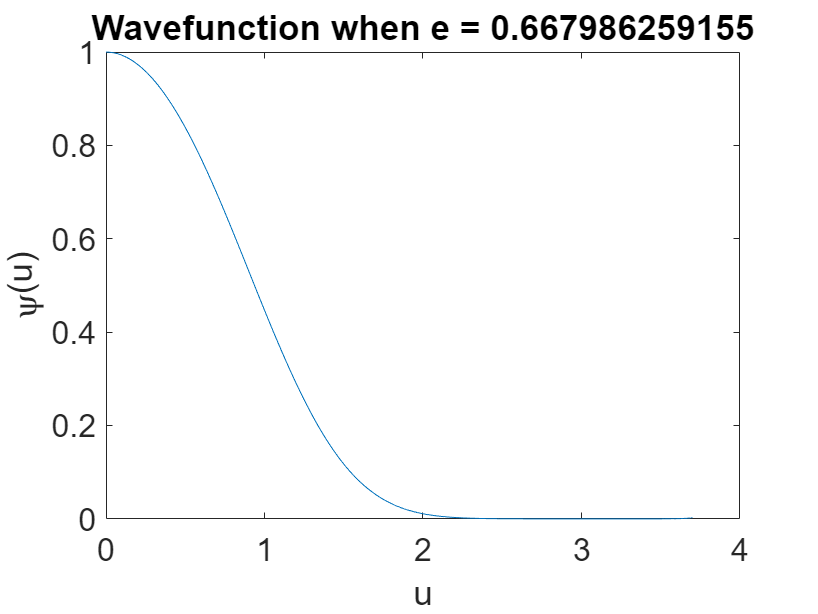


% Plot the solution
p = plot(u,soln(:,1)); % soln(:,1) means "take every row of soln, and only the first column"
p.Parent.FontSize = 16;
xlabel('u');
ylabel('\psi(u)');
title(['Wavefunction when e = ',texte]);


% Function that defines the ODE
% Note that any functions must be defined at the end of the script

function derivatives = ourderivatives(u,psi,e)
    % The psi vector is [psi(u); psi'(u)]
    % This means that psi(1) = psi(u) and psi(2) = psi'(u)
    % The derivatives vector that this function computes is [psi'(u); psi''(u)]
    % The derivative vector is [psi'(u); 2 psi(u) (u^4 - e)]
    % This must be written in terms of the psi vector
    derivatives = [psi(2); 2*psi(1)*(u^4 - e)];
end
